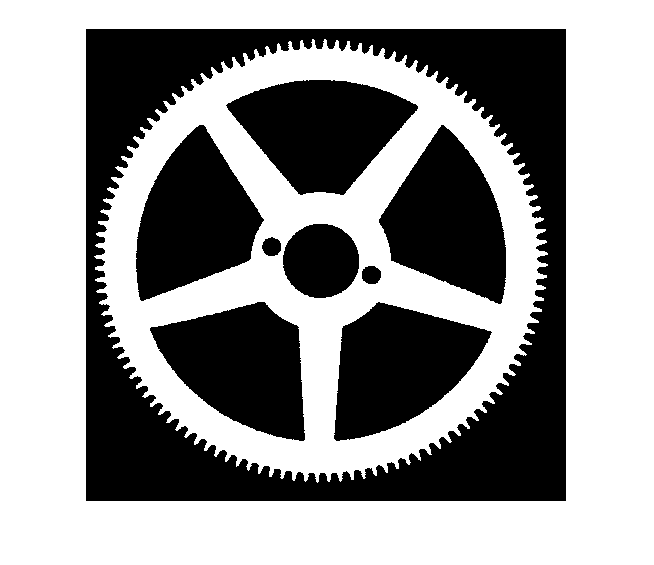

% -- EXERCICI 1 --
I = imread('Wheel.bmp');
I = rgb2gray(I);

% Binarizamos la imagen
I = not(I == 0);
imshow(I);

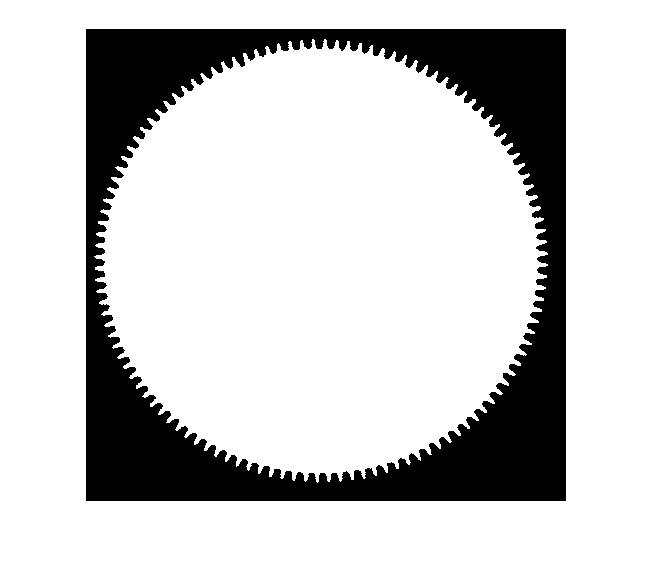

% Hacemos una reconstruccion a partir del fondo
bw = zeros(size(I));
bw(1,1) = 1;
bw = (bw == 1);
I = imreconstruct(bw, not(I));

% negamos la reconstruccion
I = not(I);
imshow(I);

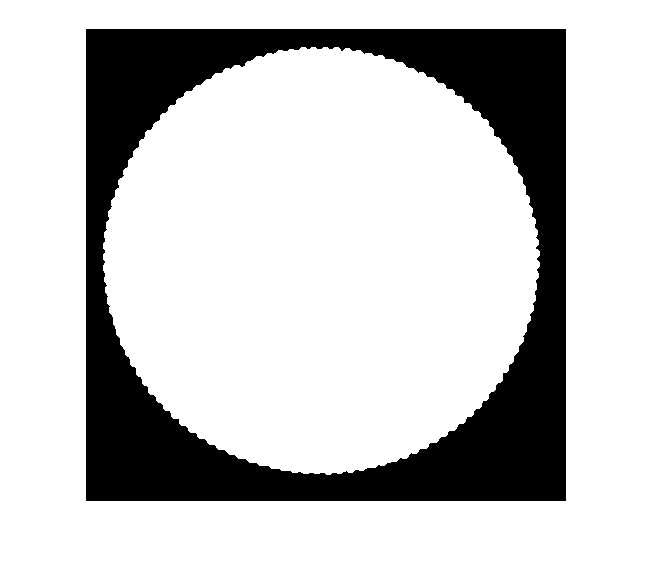


% Hacemos un opening
SE = strel('disk',5);
nodents = imopen(I, SE);
imshow(nodents);

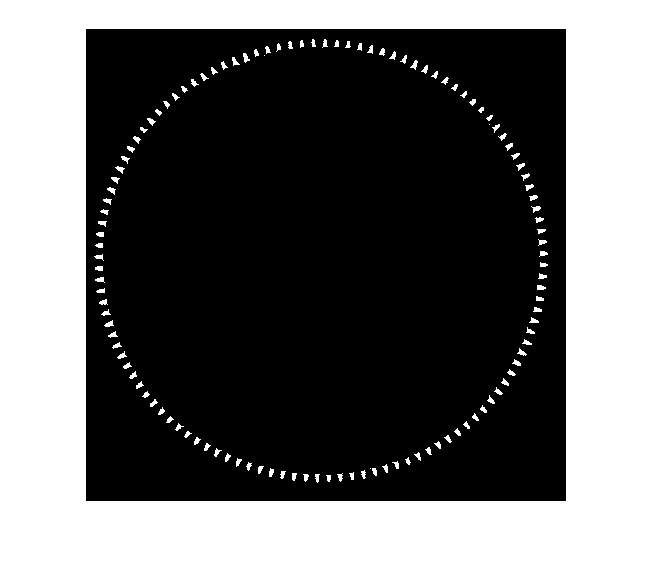


% Restamos para obtener los dientes separados
dents = xor(I, nodents);
imshow(dents);


% Calculamos cuantas componentes connexas hay
con = bwconncomp(dents2);
num = con.NumObjects

num = 120